# What is Steepest Gradient Method?

## Introduction

    因為機器學習是當今非常熱門的學習領域，而在機器學習中，通常有個損失函數(cost function 或 loss funthion，對應優化理論中的目標函數)，我們希望損失函數能夠達到最小值，這時候就需要用到梯度下降法來尋找函數最小值的解。

## Mathematical Analysis

    首先確立問題與目標：假設現在有一個已知函數$\textrm{F：}{\mathrm{R}}^{\mathrm{n}} \longrightarrow \mathrm{R}$，我們想知道其最小值的解。假設$\mathrm{F}$的等高線圖(Contour Plots)如下，則第一步：先選定第一個點 $\overrightarrow{V_0 }$，這個點需要盡量選在解的附近，以加快速度。之後，我們需要選出下一步的方向(direction)與下一步的大小(size)。

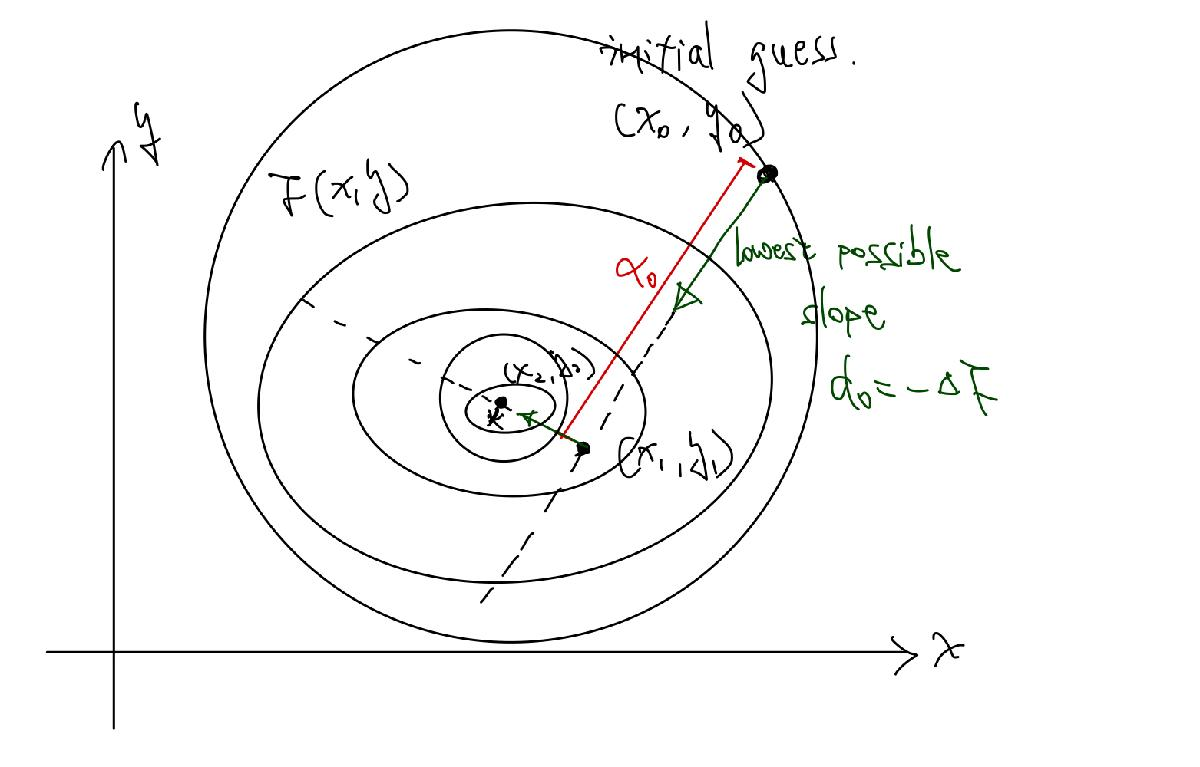

    選擇方向的方面，我們希望下一步的方向能夠使數值下降的最快，也就是說$\overrightarrow{V_0 }$在這個方向的方向導數最小。因為$F\left(\overrightarrow{V_0 } \right)$在$\overrightarrow{d_0 }$方向的方向導數為

   
$$D_{\overrightarrow{d_0 } } F\left(\overrightarrow{V_0 } \right)=\nabla F\left(\overrightarrow{V_0 } \right)\cdot \overrightarrow{d_0 }$$


由柯西不等式，我們知道當$\overrightarrow{d_0 }$與$\nabla F\left(\overrightarrow{V_0 } \right)$為反方向時，方向導數會有最小值，也就是說


$$\overrightarrow{d_0 } =\nabla F\left(\overrightarrow{V_0 } \right)$$


    接下來要決定大小。既然已經選出了最陡方向，我們就想選出這個方向上的最小值，以接近最佳解，也就是說要找到$g\left(\alpha \right)=F\left(\overrightarrow{V_0 } \;+\alpha \overrightarrow{d_0 } \right)$的最小值解。首先將$g\left(\alpha \right)$對$\alpha$微分


$$\frac{d}{d\alpha }g\left(\alpha \right)=\nabla F\left(\overrightarrow{V_0 } +\alpha \overrightarrow{d_0 } \right)\cdot \overrightarrow{d_0 }$$


，然後用解$\frac{d}{d\alpha }g\left(\alpha_0 \right)=0$，我們找到大小囉！

    最後就是無止盡的重複上述步驟，使$\overrightarrow{V_{k+1} } =\overrightarrow{V_k } +\alpha_k \overrightarrow{d_k }$，直到$\overrightarrow{V_{k+1} }$和$\overrightarrow{V_k }$之間的距離小於我們設計的容許誤差(error tolerance)。

### SDM for Ax=b

    假設A為正定對稱矩陣，讓$\textrm{F：}{\mathrm{R}}^2 \longrightarrow \mathrm{R}$定義成


$$\mathrm{F}\left(\mathbf{v}\right)=\frac{1}{2}{\mathbf{v}}^{\mathbf{T}} \textrm{Av}-{\mathbf{b}}^{\mathbf{T}} \mathbf{v}$$


則$\nabla F\left(v\right)=\textrm{Av}-b\equiv -r$

#### SDM :

                
$$\begin{array}{l}
{\mathbf{v}}_{\mathbf{k}+1} ={\mathbf{v}}_{\mathbf{k}} +\alpha_k {\mathbf{d}}_{\mathbf{k}} \\
{\mathbf{d}}_{\mathbf{k}} :\textrm{direction}\\
\alpha_k :\textrm{step}\;\textrm{size}\\
{\mathbf{d}}_{\mathbf{k}} =-\nabla \mathrm{F}\left(\mathbf{v}\right)={\mathbf{r}}_{\mathbf{k}} =\mathbf{b}-\mathbf{A}{\mathbf{v}}_{\mathbf{k}} 
\end{array}$$


#### Find $\alpha_k$:

                
$$g\left(\alpha \right)=\mathrm{F}\left(v_k +\alpha {\mathbf{d}}_{\mathbf{k}} \right)$$


                
$$\begin{array}{l}
\Rightarrow {\mathrm{g}}^{\prime } \left(\alpha \right)=\nabla F\left(v_k +\alpha d_k \right)\cdot d_k \\
\textrm{set}\;{\mathrm{g}}^{\prime } \left(\alpha_k \right)=0\\
\textrm{LHS}=\nabla F\left(v_k +\alpha_k d_k \right)\cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=\nabla F\left(v_{k+1} \right)\cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=-r_{k+1} \cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=\left(A{\mathbf{v}}_{\mathbf{k}+1} -b\right)\cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=\left(A\left(v_k +\alpha_k d_k \right)-b\right)\cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=\left(A{\mathbf{v}}_{\mathbf{k}} -b+\alpha_k Ad_k \right)\cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=\left(-r_k +\alpha_k Ad_k \right)\cdot d_k \\
\;\;\;\;\;\;\;\;\;\;=\textrm{RHS}=0\\
\Longrightarrow \alpha_k =\frac{r_k \cdot d_k }{Ad_k \cdot d_k }=\frac{r_k \cdot d_k }{q_k \cdot d_k }\;\;,\textrm{where}\;\;q_k =Ad_k =Ar_k 
\end{array}$$


## Algorithm

            Pick $\overrightarrow{V_0 }$

            For k$\ge$0

                
$$r_k =$$

$$\mathbf{b}-\mathbf{A}{\mathbf{v}}_{\mathbf{k}}$$


                
$$q_k =Ar_k$$


                
$$\alpha_k =\frac{r_k \cdot r_k }{q_k \cdot r_k }$$


                
$${\mathbf{v}}_{\mathbf{k}+1} ={\mathbf{v}}_{\mathbf{k}} +\alpha_k r_{\mathbf{k}}$$


            End

## Programming

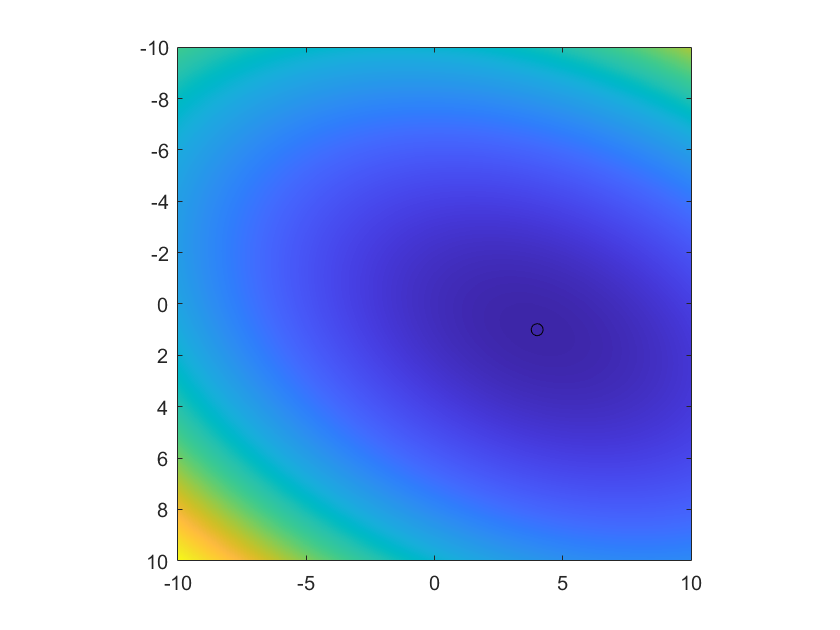

% Define A, b
A=[2 -1;-1 4];
b = [7 0]';
% Initial guess
v0 = [-10 -10]';
% The target function
Func = @(x,y) (1/2).*(A(1).*x.^2+(A(2)+A(3)).*x.*y+A(4).*y.^2)-(b(1).*x+b(2).*y);

x = linspace(-10,10,1000);
y = linspace(-10,10,1000);
[Y,X] = meshgrid(y,x);
F = Func(X,Y);

% Perform algorithm
v = inf;
tol = 1e-3;
r = inf;
k = 0;
alpha = inf;
while norm(alpha*r)>tol
    % Visualize
    imagesc(x,y,F');
    axis equal tight;
    hold on;
    plot(v0(1),v0(2),'ok')
    hold off;
    drawnow;
    pause(0.5)

    % Agorithm
    r = b - A*v0;
    q = A*r;
    alpha = dot(r,r)/dot(q,r);
    v0 = v0 + alpha*r;

    % iteration
    k = k + 1;
end

% iteration and result
k

k = 14

v0

v0 =     3.9997
    0.9998


## Numerical Results

`迭代次數：k = 14`

`最佳解：v = ``2×1`

`    3.9997`

`    0.9998`